# **RBE500: Foundations of Robotics **

# **Week 6 : Jacobian and Joint Velocity **

**Kathia Coronado**

*Robotics Engineering Graduate Student, Worcester Polytechnic Institute, Worcester, Massachussets, kcoronado@wpi.edu*

## Introduction

The goal of this weeks assignment is to revisit DENSO's HSR robot manipulator in order to conduct a jacobian analysis on it as well as gain more experience with joint velocity kinematics. The assignment also provides the opportunity to get aquantainted with MATALBS Robotic toolbox.  

**Problem 1:**

The first portion of the this assignment involved analyzing DENSO's HSR robot, shown in figure 1, using MATLAB's Robotics Toolbox to conduct a forward kinematic analysis on the system. Unlink previous assigmnent where joint values were chosen randomly, here the the first and second joints of the system are time dependent and are described using trigonometric equations, displayed in table 1. In this assignment the denso robot was was interpreted as a 4 degreee of freedom manipulator. The first, second and fourth joints are revolute and the third joint is prismatic.Figure 2, displays simplified diagram of the denso robot with labeled variables. In order to better visualize and understand the HSR Manipulator, an animation will be created that shows the interactions between the joint variables and the linkages.  

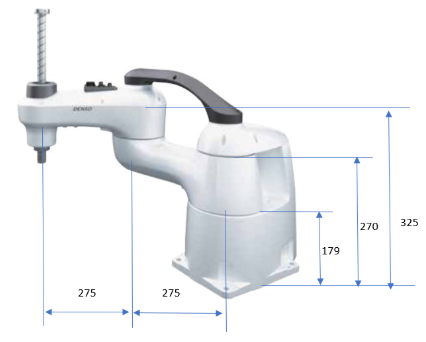

*Figure 1 -  Denso HSR series 480 mm robot with labeled assumed parameters from week 2 assignment*

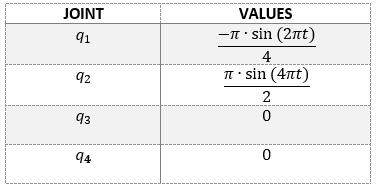

*Table 1 - Given joint values for HSR Robot *

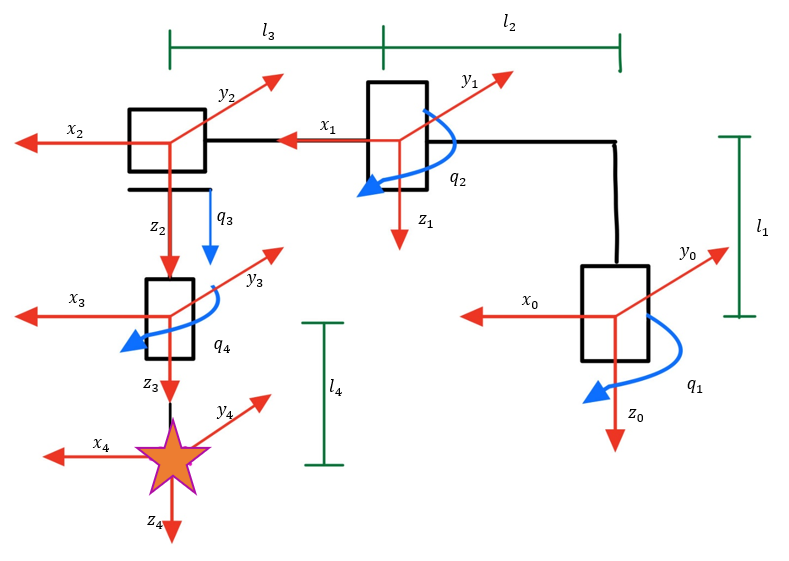

*Figure 2 - Simplified Diagram of Denso Robot*

**Problem 2:**

The second problem of this assignment also involved analyzing the DENSO HSR robot, Figure 2, however in this probelm the jacobian matrix of the system was calculated geometrically and using MATLAB's Robotic Toolbox. Both methods were compared and analyzed, by inputing random joint values and validating that both answer match. This problem also involved calculating trapazoidal velocity profiles for each link of the robot using MATLAB's Robotics Toolkit. Using these profiles, the linear and angular velocity of the last joint were plotted. 

## Methods and Materials

**Problem 1:**

**Answer :**

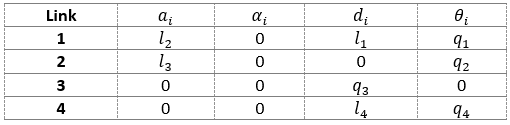

The first probelm of this assignment involved analyzing the Denso's HSR robot 480mm 100 mm z-stroke robot. This is a 4 degree of freedom robot. Using the Denso's catalog (2), the links of the robots were approximated to produce a simplified diagram of the model, see figure 1. The coordinate frames, joint angles and link lengths are labeled. The 1st frame is the base frame and contains revolute joint, the 2nd frame also contains a revolute joint, the 3rd frame has a prismatic joint and the 4th frame has another revolute joint. The 5th frame of the robot has not joint  and representss the end effector. 

 To analyze the system transformation matrices of the system must be obtained. For this analysis, the DH method was used to obtain the tranformation matrices. The DH method simplifies the analysis of a multi link manipulator by representing each HTM, $\,A_i$, as a product of four basic tranformations, see equation 3.10.

In order to use the DH method, one must first analyze the system and obtain the link length ($a_i$), link twist ($\alpha_i$), link offset ($d_i$) and joint angle ($\theta_i \,$). For this problem these DH parameters were obtained and displayed on table 2.

*Table 2 - DH parameters for DENSO HSR Robot*

Upt until now the HTM for each joint has been obtained by using these parameters and  equation 3.10, in the textbook. The goal of this problem was to obtain the the HTMs using the DH parameters and the MATLAB Robotics Toolbox. In order to do this, the system must first be simulated by the program. This is done by greating a Rigidbodytree to represent the robot. Then  creating an object for each component of the robot ( links and joints) and defining the interactions between each component. Figure 3 displays the definitions of the body links and joints that were assumed for this simulation. The type of joint is also defined for each joint

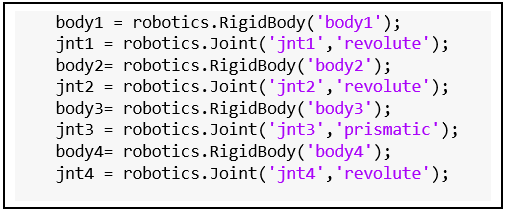

*Figure 3 - Definition of the links and joint variables to simulate the HSR Robot with Toolkit*

Using this and some other relationships (such as the order of attachment), the Homogenous transformation matrices were defines for each each joint with respect to the base. 


$$T_1^0 =$$

$$$$



$$T_2^0 =T_1^0 T_2^1 =\;\;$$

$$\left(\begin{array}{cccc}
\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)-\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right) & -\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)-\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)\,\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right) & 0 & 275\,\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)+275\,\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\,\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)-275\,\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\,\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)\\
\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\,\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)+\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)\,\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right) & \mathrm{cos}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)-\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right) & 0 & 275\,\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)+275\,\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\,\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)+275\,\mathrm{cos}\left(\frac{\pi \,q_{\mathrm{2s}} }{180}\right)\,\mathrm{sin}\left(\frac{\pi \,q_{\mathrm{1s}} }{180}\right)\\
0 & 0 & 1 & -146\\
0 & 0 & 0 & 1
\end{array}\right)\mathrm{}$$


$o_4^0 =H_4^0 \left(:,4\right)$                                                                                                                                                                            (1)

**Problem 2:**

**Answer:**


$$J=\left\lbrack \begin{array}{c}
J_w \\
J_v 
\end{array}\right\rbrack =\left(\begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & 1 & 0 & 1\\
-275\,\sin \left(\frac{\pi \,{\left(q_{\textrm{1s}} +q_{\textrm{2s}} \right)}}{180}\right)-275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right) & -275\,\sin \left(\frac{\pi \,{\left(q_{\textrm{1s}} +q_{\textrm{2s}} \right)}}{180}\right) & 0 & 0\\
275\,\cos \left(\frac{\pi \,{\left(q_{\textrm{1s}} +q_{\textrm{2s}} \right)}}{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right) & 275\,\cos \left(\frac{\pi \,{\left(q_{\textrm{1s}} +q_{\textrm{2s}} \right)}}{180}\right) & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right)\mathrm{}$$


The second problem of this assingment used the same diagram and assumptions as the first problem. In other words, figure 2 can be used for both problem 1 and problem 2. The goal of this assingmnet is to calculate the jacobian matrix of the system.  Jacobian is a matrix that relates joint velocties to linear velocities, see equation 2. 

$\left\lbrack \begin{array}{c}
v_n^0 \\
\omega_n^0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
J_v \\
j_w 
\end{array}\right\rbrack \overset{\ldotp }{q}$                                                                                                                                                                          (2)

Jacobian matrices take into account each joint, therefore in order to obtain the jacobian matrix of the system, a jacobian vector for each joint must first be calculated, I did this using equation 4.81 for revolute joints and 4.82 for prismatic joints. Equations 3a -3d are used to obtain the jacobian vector for each joint. $J_1$, $J_2$, and $J_4$ used equation 4.81 as they represent  revolute joints that have rotation. $J_3$ was found using equation 4.2 as it respresents the velocity of a prismatic joint. 

$J_1 =\left\lbrack \begin{array}{c}
z_0 \\
z_0 \times \left(o_n -o_0 \right)
\end{array}\right\rbrack =\left(\begin{array}{c}
0\\
0\\
1\\
-275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)-275\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)-275\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\\
275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)-275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\\
0
\end{array}\right)$                              (3a)

$J_2 =\left\lbrack \begin{array}{c}
z_1 \\
z_1 \times \left(o_n -o_1 \right)
\end{array}\right\rbrack =\left(\begin{array}{c}
0\\
0\\
1\\
-275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)-275\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\\
275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)-275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\\
0
\end{array}\right)$                                                       (3b)

$J_3 =\left\lbrack \begin{array}{c}
0\\
z_2 
\end{array}\right\rbrack =\left(\begin{array}{c}
0\\
0\\
0\\
0\\
0\\
1
\end{array}\right)\;$                                                                                                                                                                    (3c)

$J_4 =\left\lbrack \begin{array}{c}
z_3 \\
z_3 \times \left(o_n -o_3 \right)
\end{array}\right\rbrack =\left(\begin{array}{c}
0\\
0\\
1\\
0\\
0\\
0
\end{array}\right)$                                                                                                                                                    (3d)

In these equations the variable denoted by z is a unit vector along the direction of motion. Since the the coordinate frames of this system are all in the same orientation z is the same for all of the joints, see equation 4. This makes this calculation very simple.

$z_0 =z_1 =z_2 =z_3 =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                                              (4)

The variable denoted by o is the position vector of the joints HTM. These position vectors can easily be obtained by extracting the last column of the HTM describing the motion of each joint with respect to the base. $o_n$ is the position vector of the end effector, $o_3$ is the position vector of the fourth joint, $o_1$ is the position vector of the second joint and $o_0$ is the position vector of the first or base joint. eqaution 5a- 5d show this calculation.

$o_n$= $o_4$= $T_5^0 \left(:,4\right)=\left(\begin{array}{c}
275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)-275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\\
275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\\
q_{\textrm{3s}} -21
\end{array}\right)$                                       (5a)

$o_3$ = $T_4^0 \left(:,4\right)=\;$$\left(\begin{array}{c}
275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)-275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\\
275\,\sigma_2 +275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\\
q_{\textrm{3s}} -146
\end{array}\right)\mathrm{}$                                          (5b)

$o_2$ = $T_3^0 \left(:,4\right)=\;$$\left(\begin{array}{c}
275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)-275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\\
275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{2s}} }{180}\right)\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\\
-146
\end{array}\right)\;\;$                                         (5c)

$o_1$ = $T_2^0 \left(:,4\right)=\;$$\left(\begin{array}{c}
275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\\
275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right)\\
-146
\end{array}\right)$                                                                                                                                           (5d)

$o_0$ = $T_1^0 \left(:,4\right)=\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \;$                                                                                                                                                                     (5e)

Now equations 3a-3d can be completed by inputing the corresponding equations from 5a -5e and equations 4.  Once the jacobian vectors are obtained, the the entire jacobian matrix of the system can be obtained by coming combining the vectors, see equations 6.

$J=J_1 J_2 J_3 J_4 =J=\left\lbrack \begin{array}{c}
J_w \\
J_v 
\end{array}\right\rbrack =\left(\begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & 1 & 0 & 1\\
-275\,\sin \left(\frac{\pi \,{\left(q_{\textrm{1s}} +q_{\textrm{2s}} \right)}}{180}\right)-275\,\sin \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right) & -275\,\sin \left(\frac{\pi \,{\left(q_{\textrm{1s}} +q_{\textrm{2s}} \right)}}{180}\right) & 0 & 0\\
275\,\cos \left(\frac{\pi \,{\left(q_{\textrm{1s}} +q_{\textrm{2s}} \right)}}{180}\right)+275\,\cos \left(\frac{\pi \,q_{\textrm{1s}} }{180}\right) & 275\,\cos \left(\frac{\pi \,{\left(q_{\textrm{1s}} +q_{\textrm{2s}} \right)}}{180}\right) & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right)\mathrm{}$                            (6)

This assignment also required for the trap velocity profile to be obtiain for each of the joints in the HSR robot. Matlab Robotics toolbox has a function called trapveltraj, which calculates the trap veloctity trajectory of the system given some random wavepoints and a sample number. With this function, it is possible to obtain position, velocity and acceleration of the system. Recall with equation 2, with a jacabian matrix and joint velocity is it possible to obtain, the linear and angular velocity of the sytem. 

Using the trapveltraj function, I obtained the joint velocity and accerlation. I then plotted them as a function of time. Then useing equation 2, I was able to solve for and plot the linear velicities of the system.

## Results

### Problem 1:

 Denso Robot FK Using Matlab Robotics Tool Kit

Press button to run section and view 5 second animation of system . This portion of the code creates and labels the figure that will display the the animation 

 

clc; clear;
clf
animated_figure = figure;
title("Animated DENSO's RRP Robot Arm")
xlabel('X ')
ylabel('Y ')
zlabel('Z (mm)')
grid on
hold on
view(2)
lines = [];
origin = [0; 0; 0; 1;];
view([54 16])
animation_length_seconds = 5;
frames_per_second = 100;
steps = animation_length_seconds * frames_per_second;

Declarition of system link lengths assumed  and time interva;

l1= 146;
l2= 275;
l3= 275;
l4= 125;
t = (0:0.01:10);

Empty cell arrays that will hold all of the homogeneous tranformation matrices for the system and the position vector.

H_0_1s = {};
H_0_2s = {};
H_0_3s = {};
H_0_4s = {};
pe = [];

For loop that loops through the time increment i defined above in the above. I initially initialize the joint variables as being in the homeposition, to avoid using symbolic varibales 

for i = (1:length(t))
    
    q1 = 0; 
    q2 = 0; 
    q3 = 0;
    q4 = 0;
    

DH Patameters for the system. This will be used for the forward kinematics analysis of the system in order to obtain the homogenous tranformation matrices that describe joint interactions .

    a = [ l2; l3; 0; 0];
    alpha = [0;0;0;0];
    d = [-l1;0; q3; l4];
    theta = [q1; q2; 0; q4];
    dhparams = [a alpha d theta];

This portion of the code utilizes the MATLAB Robotic Toolbox .

First I create a rigidbody tree for the system. 

    %Create a rigid body tree
    robot = robotics.RigidBodyTree;
   

Then I define each link and joint in the system. When defining the joints in the system it is imprtant to accurately mark the type if joint that the variable is ( revolute, prismatic or fixed).

    body1 = robotics.RigidBody('body1');
    jnt1 = robotics.Joint('jnt1','revolute');
    body2= robotics.RigidBody('body2');
    jnt2 = robotics.Joint('jnt2','revolute');
    body3= robotics.RigidBody('body3');
    jnt3 = robotics.Joint('jnt3','prismatic');
    body4= robotics.RigidBody('body4');
    jnt4 = robotics.Joint('jnt4','revolute');
   

This porttion of the code related and accurately pairs the declared joint values with the the definded DH parameters 

 
    setFixedTransform(jnt1,dhparams(1,:),'dh');
    setFixedTransform(jnt2,dhparams(2,:),'dh');
    setFixedTransform(jnt3,dhparams(3,:),'dh');
    setFixedTransform(jnt4,dhparams(4,:),'dh');

Pairing of the links with the appropriate varaibles 

    body1.Joint = jnt1;
    body2.Joint = jnt2;
    body3.Joint = jnt3;
    body4.Joint = jnt4;

Create attachments between the objects. All of the parts are part of the same robot therefore they are all linked together.

    %attach the bodies
    addBody(robot,body1,'base');
    addBody(robot,body2,'body1');
    addBody(robot,body3,'body2');
    addBody(robot,body4,'body3');

Robot at Home configuration.

    %Robot configuration
    config = homeConfiguration(robot);
    H04_home = getTransform(robot,homeConfiguration(robot),'body4','base');
    

Refining the problem given configuration for the jointn variables 

    config(1).JointPosition = -pi/4*sin(2*pi*t(i));
    config(2).JointPosition =pi/2*sin(4*pi*t(i));
    config(3).JointPosition = 0;
    config(4).JointPosition = 0;
    

Obtaining the HTM for each joint with respect to the base of the robot. 

    H_0_4= getTransform(robot,config,'body4','base');
    H_0_3= getTransform(robot,config,'body3','base');
    H_0_2= getTransform(robot,config,'body2','base');
    H_0_1= getTransform(robot,config,'body1','base');
    
    %save coordinates 
    H_0_1s{end + 1} = H_0_1;
    H_0_2s{end + 1} = H_0_2;
    H_0_3s{end + 1} = H_0_3;
    H_0_4s{end + 1} = H_0_4;
    
        
end

Animation portion of the code.

Loop through the declared frames

for step = 1:steps
    
    % Clear previous lines
    for index = 1:length(lines)
        delete(lines(index));
    end
    lines = [];
    

Draw the links of the robot and label the coordinate frame vectors.

    [x_line, y_line, z_line] = draw_coordinate_axis(eye(4), 5, 'red', 'blue', 'green');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_1s{step}, 5, 'red', 'blue', 'green');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_2s{step}, 5, 'red', 'blue', 'green');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_3s{step}, 5, 'red', 'blue', 'green');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    
    [x_line, y_line, z_line] = draw_coordinate_axis(H_0_4s{step}, 5, 'red', 'blue', 'green');
    lines(end+1) = x_line;
    lines(end+1) = y_line;
    lines(end+1) = z_line;
    

Obtain position vector from each HTM 

    % Draw the links
    p_1 = H_0_1s{step} * origin;
    p_2 = H_0_2s{step} * origin;
    p_3 = H_0_3s{step} * origin;
    p_4 = H_0_4s{step} * origin;
    
    lines(end+1) = line('XData', [origin(1) p_1(1)], 'YData', [origin(2) p_1(2)], 'ZData', [origin(3) p_1(3)], 'Color', 'black', 'LineWidth', 2);
    lines(end+1) = line('XData', [p_1(1) p_2(1)], 'YData', [p_1(2) p_2(2)], 'ZData', [p_1(3) p_2(3)], 'Color', 'blue', 'LineWidth', 2);
    lines(end+1) = line('XData', [p_2(1) p_3(1)], 'YData', [p_2(2) p_3(2)], 'ZData', [p_2(3) p_3(3)], 'Color', 'cyan', 'LineWidth', 2);
    lines(end+1) = line('XData', [p_3(1) p_4(1)], 'YData', [p_3(2) p_4(2)], 'ZData', [p_3(3) p_4(3)], 'Color', 'magenta', 'LineWidth', 2);
    plot3(p_4(1),p_4(2),p_4(3),'*');
 
    pause(1/frames_per_second) 
    
end
hold off


Plot the tip of the end effector.Plot the tip of the end effector.

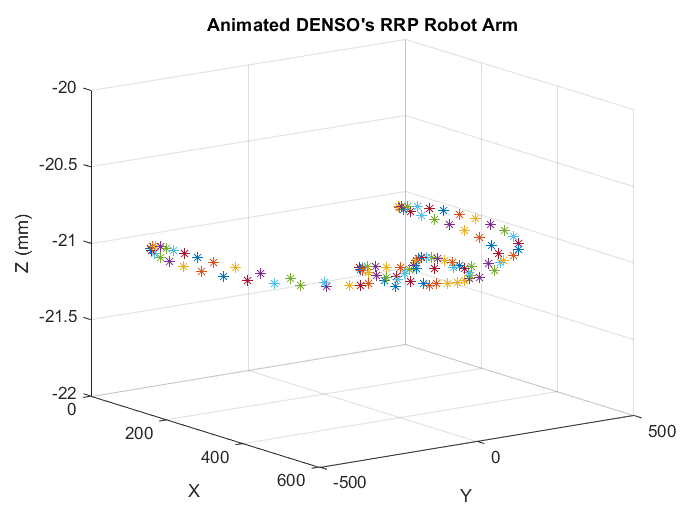


figure;
view(2)
hold on
for  step = 1:steps
    
    for index = 1:length(lines)
        delete(lines(index));
    end
    lines = [];
    p_4 = H_0_4s{step} * origin;
    plot3(p_4(1),p_4(2),p_4(3), '-o' );  
end

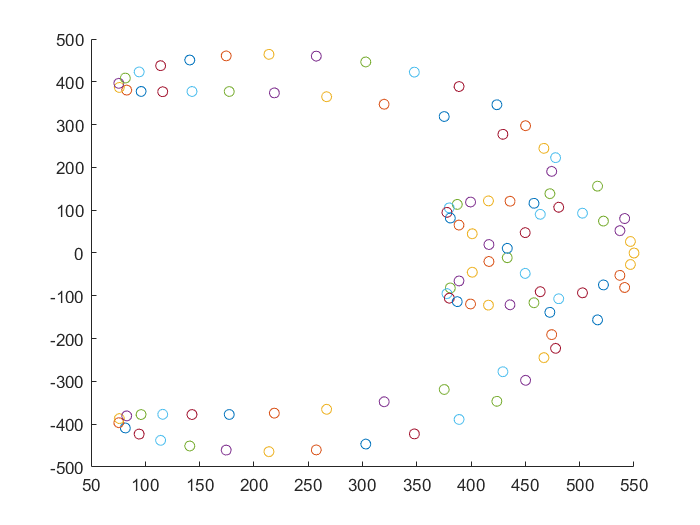

hold off;

### Problem 2:

#### Method 1 : Gemetric Jacobian Using the  MATLAB Robotics Toolkit 

Declaration of system link lengths and initial home position joint variables 

clc;clear;

l1= 146;
l2= 275;
l3= 275;
l4= 125;
 
q_1 = 0;
q_2 = 0;
q_3 = 0;
q_4 = 0;

DH parameters for Forward kinematic analysis to obtain the HTMs of the system

a = [ l2; l3; 0; 0];
alpha = [0;0;0;0];
d = [-l1;0; q_3; l4];
theta = [q_1; q_2; 0; q_4];
dhparams = [a alpha d theta];


Define the body tree for the robot, in order to simulate it 

%Create a rigid body tree
robot = robotics.RigidBodyTree;


Then I define each link and joint in the system. When defining the joints in the system it is imprtant to accurately mark the type if joint that the variable is ( revolute, prismatic or fixed).

%Define the bodies and their joints
body1 = robotics.RigidBody('body1');
jnt1 = robotics.Joint('jnt1','revolute');
body2= robotics.RigidBody('body2');
jnt2 = robotics.Joint('jnt2','revolute');
body3= robotics.RigidBody('body3');
jnt3 = robotics.Joint('jnt3','prismatic');
body4= robotics.RigidBody('body4');
jnt4 = robotics.Joint('jnt4','revolute');
    

This porttion of the code related and accurately pairs the declared joint values with the the definded DH parameters 

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

Pair links and variables 

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

Create attachments between the objects. All of the parts are part of the same robot therefore they are all linked together.

    %attach the bodies
addBody(robot,body1,'base');
addBody(robot,body2,'body1');
addBody(robot,body3,'body2');
addBody(robot,body4,'body3');

Declare configuration of robot, by putting in joint values 

%Robot configuration
config = homeConfiguration(robot);
config(1).JointPosition = deg2rad(20);
config(2).JointPosition = deg2rad(30);
config(3).JointPosition = 4;
config(4).JointPosition = deg2rad(25);

Obtain geometric jacobian using matlab function

jacobian = geometricJacobian(robot,config, 'body4')

jacobian =          0         0         0         0
         0         0         0         0
    1.0000    1.0000         0    1.0000
 -304.7178 -210.6622         0         0
  435.1821  176.7666         0         0
         0         0    1.0000         0


#### **Method 2**: Jacobian using the geometric jacobian

clear ; clc;
syms q_1s q_2s q_3s q_4s

link lengths

l1= 146;
l2= 275;
l3= 275;
l4= 125;

DH parameters for FK 

a = [ l2; l3; 0; 0];
alpha = [0;0;0;0];
d = [-l1;0; q_3s; l4];
theta = [q_1s; q_2s; 0; q_4s];
A = GetDH(a, alpha, d, theta);

HTM from each link to base of robot

T01 = A{1};
T02 = A{1}*A{2};
T03 = A{1}*A{2}*A{3};
T04 = A{1}*A{2}*A{3}*A{4};


Position vector for each link with respect to base of the robot

o0 = [0;0;0];

o0 =      0
     0
     0


o1 = expand(T01(1:3,4));

$$o1 = \left(\begin{array}{c} 275\,\cos\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right)\\ 275\,\sin\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right)\\ -146 \end{array}\right)$$

o2 = expand(T02(1:3,4));

$$o2 = \begin{array}{l} \left(\begin{array}{c} 275\,\sigma_{1}+275\,\sigma_{1}\,\cos\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)-275\,\sigma_{2}\,\sin\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)\\ 275\,\sigma_{2}+275\,\sigma_{1}\,\sin\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)+275\,\cos\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)\,\sigma_{2}\\ -146 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right) \end{array}$$

o3 = expand(T03(1:3,4));

$$o3 = \begin{array}{l} \left(\begin{array}{c} 275\,\sigma_{1}+275\,\sigma_{1}\,\cos\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)-275\,\sigma_{2}\,\sin\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)\\ 275\,\sigma_{2}+275\,\sigma_{1}\,\sin\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)+275\,\cos\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)\,\sigma_{2}\\ q_{\mathrm{3s}}-146 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right) \end{array}$$

o4 = expand(T04(1:3,4));

$$o4 = \begin{array}{l} \left(\begin{array}{c} 275\,\sigma_{1}+275\,\sigma_{1}\,\cos\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)-275\,\sigma_{2}\,\sin\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)\\ 275\,\sigma_{2}+275\,\sigma_{1}\,\sin\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)+275\,\cos\left(\frac{\pi \,q_{\mathrm{2s}}}{180}\right)\,\sigma_{2}\\ q_{\mathrm{3s}}-21 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right) \end{array}$$

 unit vectors in direction of motion 

z0 = [0;0;1];
z1 = T01(1:3,1:3)*[0;0;1];
z2 = T02(1:3,1:3)*[0;0;1];
z3 = T03(1:3,1:3)*[0;0;1];
%z4 = T04(1:3,1:3)*[0;0;1];


Calculating the jacobian of each joint 

j1 = [z0 ; cross(z0,(o4-o0))];
j2 = [z1 ; cross(z1,(o4-o1))];
j3 = [0;0;0;z2]; % prismatic 
j4 = [z3;cross(z3,(o4-o3))];
jv =simplify([cross(z0,(o4-o0)) cross(z1,(o4-o1)) z2 cross(z3,(o4-o3))]);
jw =[ z0 z1 [0;0;0] z3];

Put it all together to get the full jacobian of the system.  Here i did [Jw ; Jv] since this is the notation that matlab uses . 

Substitute random values in order to compare both calculations of jacoian 

J= simplify([j1 j2 j3 j4])

$$J = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 0 & 1\\ -\sigma_{1}-275\,\sin\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right) & -\sigma_{1} & 0 & 0\\ \sigma_{2}+275\,\cos\left(\frac{\pi \,q_{\mathrm{1s}}}{180}\right) & \sigma_{2} & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=275\,\sin\left(\frac{\pi \,\left(q_{\mathrm{1s}}+q_{\mathrm{2s}}\right)}{180}\right)\\ \sigma_{2}=275\,\cos\left(\frac{\pi \,\left(q_{\mathrm{1s}}+q_{\mathrm{2s}}\right)}{180}\right) \end{array}$$

J_sub= double(subs(J, {q_1s q_2s q_3s q_4s}, {20 30 4 25}))

J_sub =          0         0         0         0
         0         0         0         0
    1.0000    1.0000         0    1.0000
 -304.7178 -210.6622         0         0
  435.1821  176.7666         0         0
         0         0    1.0000         0


Trapvelocity profiles for each joint calculation. Random waypoints were chosen to and the parameters were calculated. 

clf
%Trapvelocity
wp1 = [-15 15 0 45 15 120]*pi/180;
[q1, qd1, qdd1, tvec1, pp1] = trapveltraj(wp1, 501); % Pos and vel for joint1
wp2 = [-15 25 0 -25 0 45]*pi/180;
[q2, qd2, qdd2, tvec2, pp2] = trapveltraj(wp2, 501); % Pos and vel for joint2
wp3 = [5 10 15 0 35 26];
[q3, qd3, qdd3, tvec3, pp3] = trapveltraj(wp3, 501); % Pos and vel for joint3
wp4 = [-35 10 0 -25 15 45]*pi/180;
[q4, qd4, qdd4, tvec4, pp4] = trapveltraj(wp4, 501); % Pos and vel for joint4

Plot position as a function of time for eahc joint 

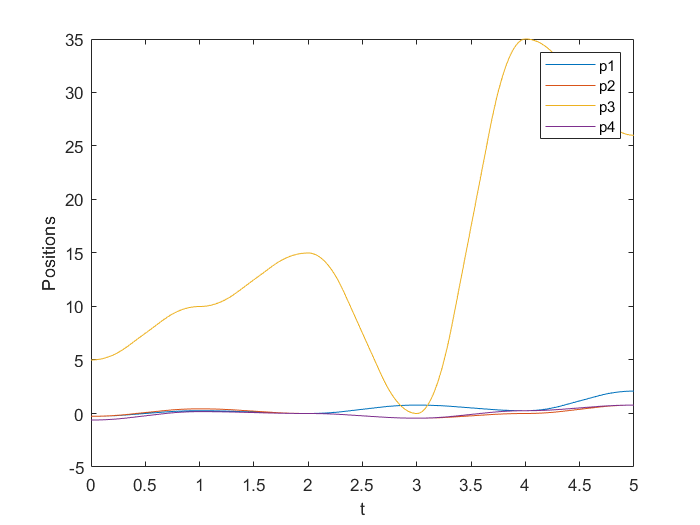

figure(1)
plot(tvec1,q1)
hold on 
plot(tvec2,q2)
plot(tvec3,q3)
plot(tvec4,q4)
xlabel('t')
ylabel('Positions')
legend('p1','p2','p3','p4')
hold off

Plot joint velocity as a a function of time for each joint 

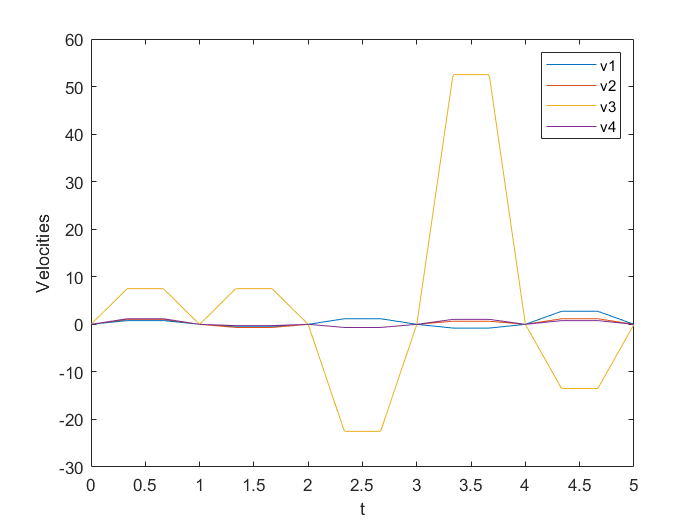

figure(2)
plot(tvec1,qd1)
hold on 
plot(tvec2,qd2)
plot(tvec3,qd3)
plot(tvec4,qd4)
xlabel('t')
ylabel('Velocities')
legend('v1','v2','v3','v4')
hold off

Plot acceleration asa function of time for each joint 

figure(3)
plot(tvec1,qdd1)
hold on 
plot(tvec2,qdd2)
plot(tvec3,qdd3)
plot(tvec4,qdd4)
xlabel('t')
ylabel('Accelerations')
legend('a1','a2','a3','a4')
hold off

q= [q1;q2;q3;q4];
qdot = [qd1;qd2;qd3;qd4];
qddot = [qdd1;qdd2;qdd3;qdd4];
te = [tvec1;tvec2;tvec3;tvec4];



Loops through all of the samples and substitutes the values into the jacobian and then obtains the instaneous velocity and accerleration at those specific sample configuratiion

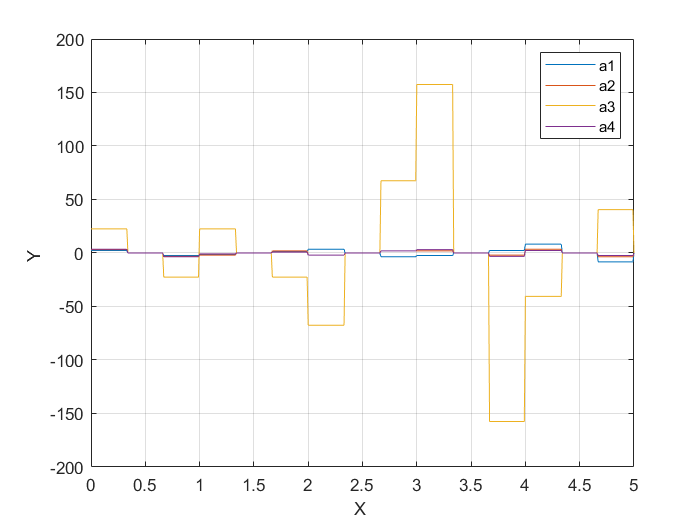

figure(4);
title("Velocity of HSR")
xlabel('Xd ')
ylabel('Yd ')
zlabel('Zd ')
grid on

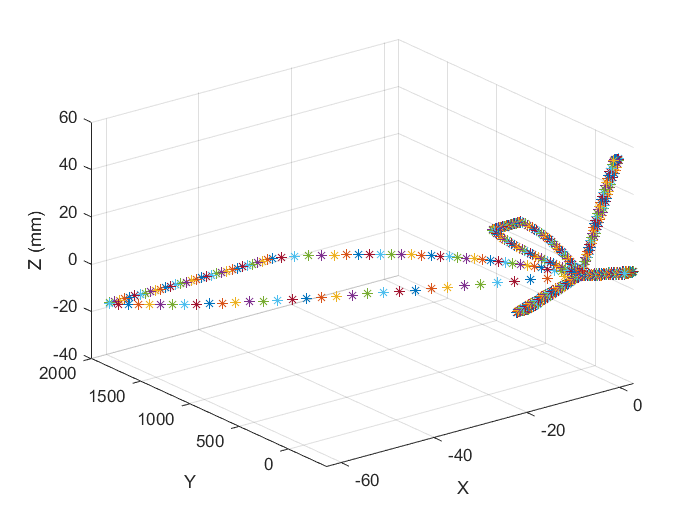

for i = 1:501
pos = [q1(i) q2(i) q3(i) q4(i)];
angvel = [qd1(i) qd2(i) qd3(i) qd4(i)];
angacc = [qdd1(i) qdd2(i) qdd3(i) qdd4(i)];

jv_sub= double(subs(jv, {q_1s q_2s q_3s q_4s}, pos));
vi = jv_sub*transpose(angvel);


vx = vi(1);
vy = vi(2);
vz = vi(3);

plot3(vx,vy,vz,'*')
hold on
end
hold off 


figure (5)
title("Acceleration of HSR")
xlabel('Xdd ')
ylabel('Ydd ')
zlabel('Zdd ')
grid on

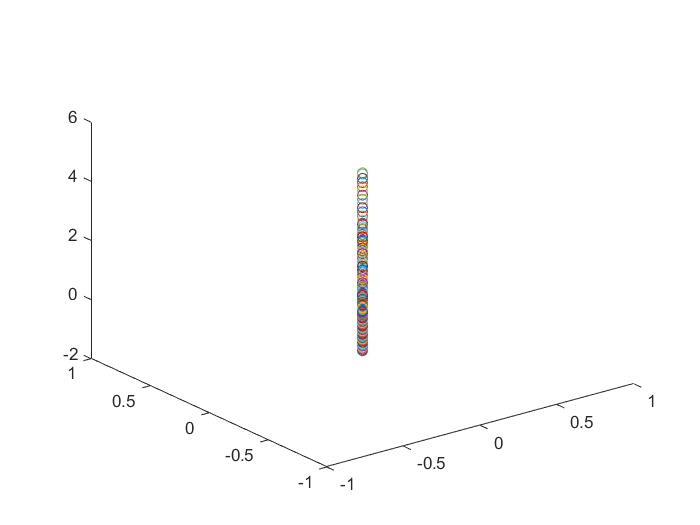

for i = 1:501
pos = [q1(i) q2(i) q3(i) q4(i)];
angvel = [qd1(i) qd2(i) qd3(i) qd4(i)];
angacc = [qdd1(i) qdd2(i) qdd3(i) qdd4(i)];

jw_sub= double(subs(jw, {q_1s q_2s q_3s q_4s}, pos));
wi = jw_sub*transpose(angvel);


wx = wi(1);
wy = wi(2);
wz = wi(3);

plot3(wx,wy,wz,'o')
hold on 

end
hold off

#### **Functions **

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end

This function uses the DH parameter to calculated the HTM using the DH method. This function will work for any number of joints. The output of this function is a cell array

function A = GetDH (a, alpha,d,theta)
A = {};
for i = (1:length(a))
    
    H = [ cosd(theta(i)) -sind(theta(i))*cosd(alpha(i)) sind(theta(i))*sind(alpha(i)) a(i)*cosd(theta(i));
         sind(theta(i)) cosd(theta(i))*cosd(alpha(i)) -cosd(theta(i))*sind(alpha(i)) a(i)*sind(theta(i));
         0 sind(alpha(i)) cosd(alpha(i)) d(i);
         0 0 0 1];
    A{i}= H;
end
end

The purpose of this function is to get the tranformation matrix of the end effector with respect to the base. The input of this function is a cell array of all of the homogeneous tranformation matrices of the system in order. This will work for systems with any number of joints.

function T= getT(A)

T= eye(4);
for j = (1: length(A(:,:,1)))
    T= T * A{j};
end
end

## Discussion

Problem 1 of this weeks assignment was very interesting as it involved learning more about matlab, and also gave the studnet freedom to experiment a bit and get better at matlab. In problem 1 I used the robotics toolkit to do forward kinematics on the HSR robot, given two trigonometric equations descirbing the behavior of the first and second joint. I was able to get the HTM for all the joints, plot the position of the end effector and animate the motion of the links. The plot produced by the position of the end effector was horse shoe shapped, this makes  sense with the sinosodial joint input that was used. All in all, the results of this problem look correct

Problem 2 Also involved analyzing the HSR Robot from problem 1, but this time the goal was to obtain the jacobian matrix of the system. I did the geometric jacobian calculation by hand and then compared it to the calculation i obtained using matlab's built in function. They two jacobian matrices were identity, so I am incline to think that the calculation was correct. The second portion of this problem involved obtaining the trap velocity profiles of the joints, and then plotting them and get linear velocity plots. Using matlab's built in function for, i was able to obtain the values that were needed to use jacobian to obtain linear velocities. All in all that portion of the calculation seem correct. I also plotted the acceleration, velocity and position with repect to time and obtained very interesting plots. I noted that in all three joint three seemed to have the biggest magnitude in position, velocity and acceleration. Joint threes is the prismatic joint and looking at the video for the HSR robot, it does seem to accelerate and move quet quickly, so i see these results being correct. 

 All in all, I really enjoyed this weeks assignment, as it involved learning alot of new things that I hadnt learned before, such as matlab robotics toolbox. in the beginning there was a little bit of learning curve, but now I see how valueable and time saving it is. My favorite part of this assignmnet was problem 1, it was awesome finally getting the animations to work and also playing around with the toolbox. I definitely learned the most with problem 1.

## References 

(1) Spong et al. (2020).* Robot Modeling and Control *(2nd Edition). Wiley.

(2) Chester, Kieth (2021). *Chester_Week4*. 